## IV Praktikum 2022

### Vorbereitungsteil:

#### Aufgabe 1


$$|E| = \frac{1}{\sqrt2} 1V,
 $$
 
$$R_1=R_2=R=50 \Omega$$


#### 1. Bestimmen Sie Pmax. 

 
$$P_{max} = \frac{|E|^2}{4R}$$
    


$$|E|^2 = \left( \frac{1V} {\sqrt{2}} \right)^2$$
 
$$ \Rightarrow  $$
   
$$|E|^2 = \frac{1}{2}V^2
$$


$P_{max} = \frac{\frac{1V^2}{2}}{4R} = \frac{1V^2}{8R} = \frac 1 {400}  \frac {V^2} \Omega
$ $=2,5
$mW  

syms R E
P_max = abs(E)^2/(4*R)

$$P\_max = \frac{{\left|\text{E}\right|}^{2}}{4\,R}$$

P_max = double(subs(P_max,[E,R],[1/sqrt(2),50]))*1000  %W --> mW

P_max = 2.5000

#### 2. Bestimmen Sie S21(jω).


$$S_{21} = k \frac {U_2} E = 2 \sqrt \frac{R_1} {R_2} \frac {U_2} {U_1} \frac{U_1} {E}$$
  
$$\Rightarrow$$
 
$$S_{21} = 2 \frac {U_2} E$$



$$U_2 = I * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \\
I = \frac E {R_{ges}}$$
  
$$\Rightarrow$$
 
$$U_2 = \frac E {R_{ges}} * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \rightarrow  S_{21} = 2 \frac { \left( R_2+ \frac 1 {j\omega C} \right)^{-1}} {R_{ges}}$$



$$R_{ges} =  R + C||R \\
C||R = \frac1 {j \omega C+\frac 1 R}$$
        
$$\Rightarrow
$$
     
$$R_{ges} = R + \frac 1 {j \omega C + \frac 1 R}$$
  


$$S_{21} = 2 \frac { \left( \frac 1 R+ j\omega C \right)^{-1}} {R+ \frac R {j \omega C R + 1}} $$


syms R omega C real
R_ges = R + 1/(1i*omega*C+1/R);
S_21 = 2*((1/R+1i*omega*C)^-1)/(R+R/(1+1i*omega*C*R)) %2*R/R_ges

$$S\_21 = \frac{2}{\left(\frac{1}{R}+C\,\omega \,\mathrm{i}\right)\,\left(R+\frac{R}{1+C\,R\,\omega \,\mathrm{i}}\right)}$$

simplify(S_21,"Steps",640)

$$ans = \frac{2}{2+C\,R\,\omega \,\mathrm{i}}$$

#### 3. Bestimmen Sie |S21(jω)|² und AdB(ω).

simplify(abs(S_21)^2,"Steps",100)

$$ans = \frac{4\,R^{2}\,{\left|C\,R\,\omega -\mathrm{i}\right|}^{2}}{{\left|C\,R\,\omega -2\,\mathrm{i}\right|}^{2}\,{\left|1+C\,R\,\omega \,\mathrm{i}\right|}^{2}\,{\left|R\right|}^{2}}$$

S21 = 4/(C^2*R^2*omega^2 + 4) - (2i*C*R*omega)/(C^2*R^2*omega^2 + 4)

$$S21 = \frac{4}{C^{2}\,R^{2}\,\omega^{2}+4}-\frac{2\,C\,R\,\omega \,\mathrm{i}}{C^{2}\,R^{2}\,\omega^{2}+4}$$

simpS21_abs_quad = (4*C^2*R^2*omega^2)/(C^2*R^2*omega^2 + 4)^2 + 16/(C^2*R^2*omega^2 + 4)^2

$$simpS21\_abs\_quad = \frac{16}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}+\frac{4\,C^{2}\,R^{2}\,\omega^{2}}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}$$

A_db = 10*log10((C^2*R^2*omega^2 + 4)^2/(4*C^2*R^2*omega^2+16))

$$A\_db = \frac{10\,\log\left(\frac{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}{4\,C^{2}\,R^{2}\,\omega^{2}+16}\right)}{\log\left(10\right)}$$

simA_db = simplify(A_db,"Steps",100)

$$simA\_db = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

#### 4. Zeichnen Sie AdB(ω) qualitativ. 

A_dB = symfun(simA_db,[C,R,omega])

$$A\_dB(C, R, omega) = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

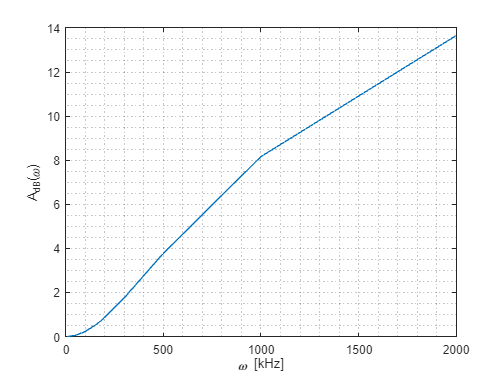

f = [10 50 90 100 150 170 180 200 300 500 1000 2000]*10^3; %kHZ

%f = 1000:1000:2000000;
plot(f./10^3,A_dB(15*10^-9,50,2*pi*f)) %C-Wert aus letzte Aufgabe
xlabel ("\omega [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")

#### 5. Handelt es sich um ein Hochpass- oder ein Tiefpassfilter? Begründen Sie Ihre Antwort.

Tiefpass, da tiefe Frequ. eine geringe Dämpfung haben und hohe Freq. eine hohe Dämpfung.

#### 6. Bestimmen Sie C in Abhängigkeit von der Durchlasskreisfrequenz $\omega_g$ und dem Rippel im Durchlassbereich $A_D$. Nutzen Sie dazu den Ansatz $A_{dB}(\omega_g) = A_D$. 

syms A_D
formula = solve(simA_db==A_D,C,"ReturnConditions",true);
formula.C(2)

$$ans = \frac{2\,\sqrt{10^{A_{D}/10}-1}}{R\,\omega }$$

#### 7. Bestimmen Sie den Wert von C für $f_g = 100kHz$ und $A_D = 0.28dB$. Runden Sie Ihr Ergebnis auf den nächsten in der E6-Bauteilreihe1 verfugbaren Wert.

double(subs(formula.C(2),[A_D R omega], [0.28 50 2*pi*10^5]))*10^9  %%F --> nF

ans = 16.4288

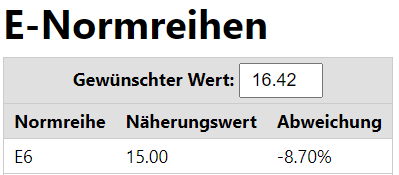

C_value = 15 %nF

C_value = 15

#### Aufgabe 7

Aufbau Bild:

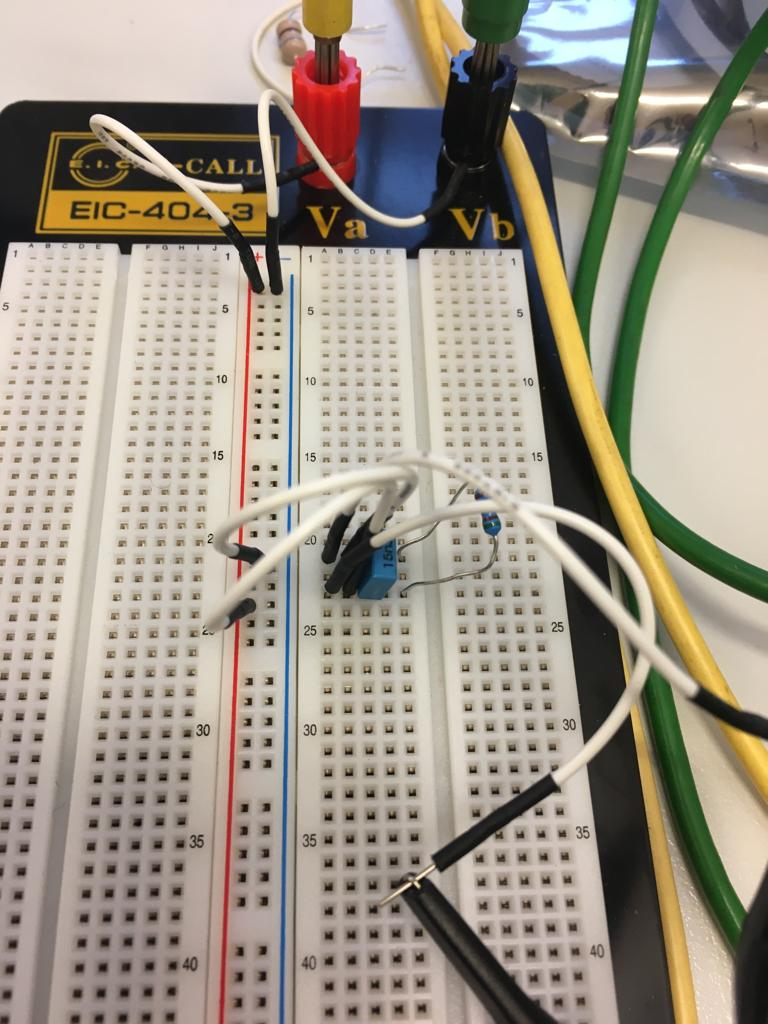

Vorgehensweiße:

#### Aufgabe 8/9/11 :

Zuerst muessen die Vorgegeben Werte auf dem Generator einigestellt werden. 100kHz und 1VPP:

Beim Anschalten des Ozsi. wird das Signal mit dem Auto-Detect Knopf detektiert. Fuer die Ablesung der Amplitude muss noch vertikal rein gezoomt werden.

Die Amplitude hatte ein Wert von 58.8 mW und eine Periodendauer von 10$\mu s$ (siehe Screenshot). 

Periodendauer $10\mu s$

Amplitude: $58.8 mW$

#### Aufgabe 10

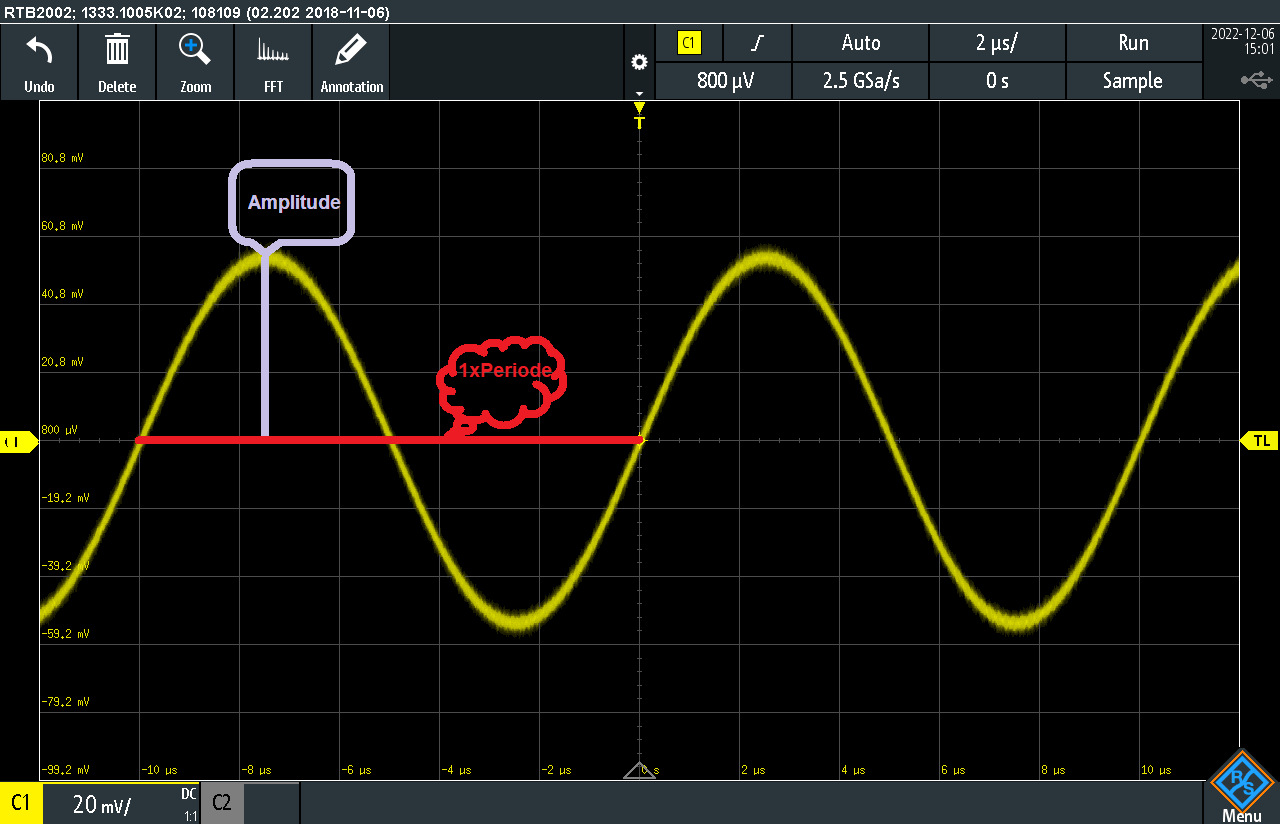

#### 12.

$f = \frac 1 {T}$ mit  $T = 10 \mu s$ 

f = 1/(10^-5)/1000 %kHz

f = 100.0000

#### 13.

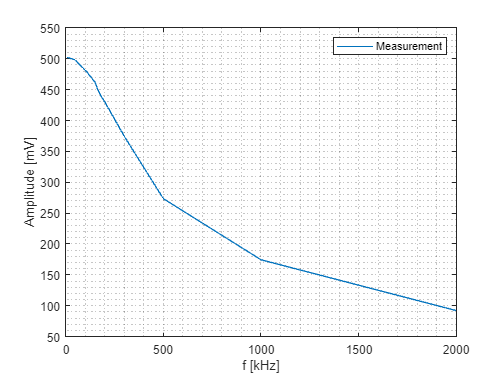

f = [10 50 90 100 150 170 180 200 300 500 1000 2000]; %kHZ
Periodendauer = f.^-1*1000; %Mikrosekundend
Amplidtude = [502 498 484 482 462 445.9 440.02 430.22 374.36 273.42 174.44 92.12]; %mW
plot(f,Amplidtude)
xlabel("f [kHz]")
ylabel("Amplitude [mV]")
grid("minor")
legend("Measurement")

Mit steigender Frequenz sinkt die Amplitdue. (Tiefpass verhalten)

#### 14.

S21_value = 2*Amplidtude./10^3

S21_value =     1.0040    0.9960    0.9680    0.9640    0.9240    0.8918    0.8800    0.8604    0.7487    0.5468    0.3489    0.1842


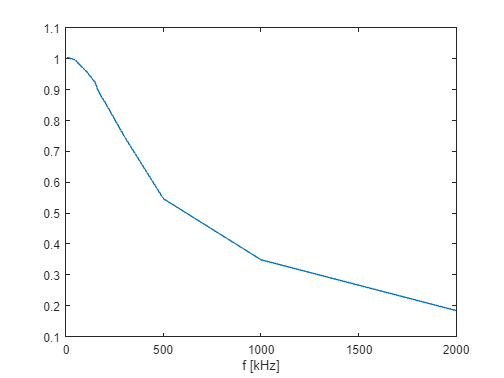

clf
plot(f,S21_value)
xlabel("f [kHz]")

#### 14.

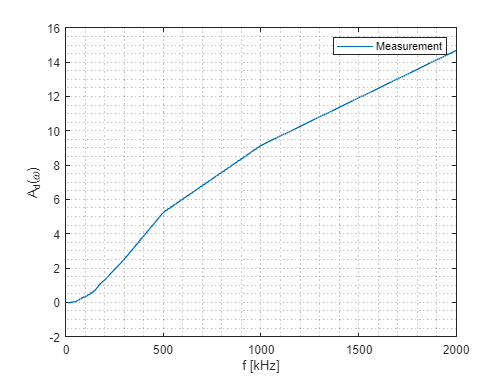

clf
plot(f,double(10*log10(S21_value.^-2)))
grid("minor")
xlabel("f [kHz]")
ylabel("A_d(\omega)")
legend("Measurement")

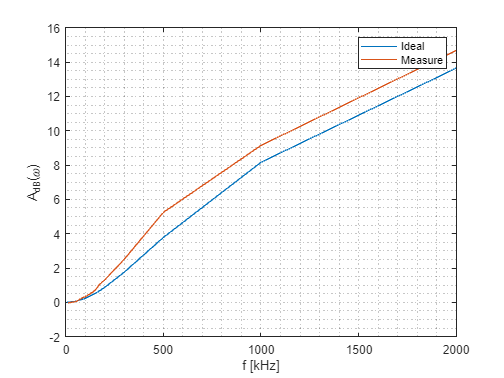

clf
plot(f,A_dB(15*10^-9,50,2*pi*f*10^3)) %C-Wert aus letzte Aufgabe
xlabel ("f [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")
hold on
plot(f,double(10*log10((2*Amplidtude*10^-3).^-2)))
legend("Ideal", "Measure")
hold off

Die Abweichungen lassen sich unter anderem durch Messrauschen und nicht Idealen Komponenten (Abweichungsnormen) erklären.

## Aufgabe 2

- $\Omega_s < 2$  --> n=3 (siehe Filtertabelle)

- 
$$\Theta = 30$$
 
$$r_1 = r_2 = 1$$
